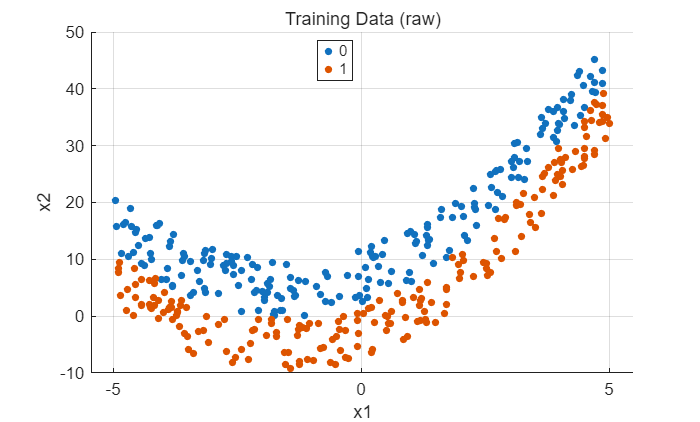

%% SVM RBF demo (MATLAB 2025a)
% 对应你的 Python / R 代码逻辑：生成数据 -> 画图 -> 训练RBF SVM -> gamma循环 -> 网格搜索

clear; clc; close all;tic

nPerClass = 200;

% 1) 生成训练集/测试集（可复现）
trainTbl = makeDataset(nPerClass, 42);
testTbl  = makeDataset(nPerClass, 202);

plotScatter(trainTbl, "label", "Training Data (raw)");

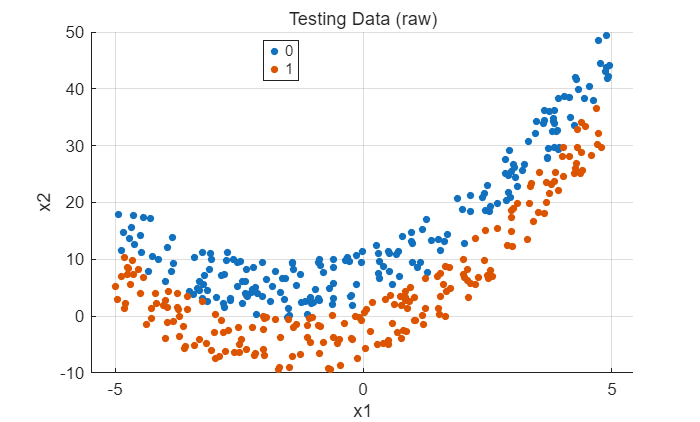

plotScatter(testTbl,  "label", "Testing Data (raw)");

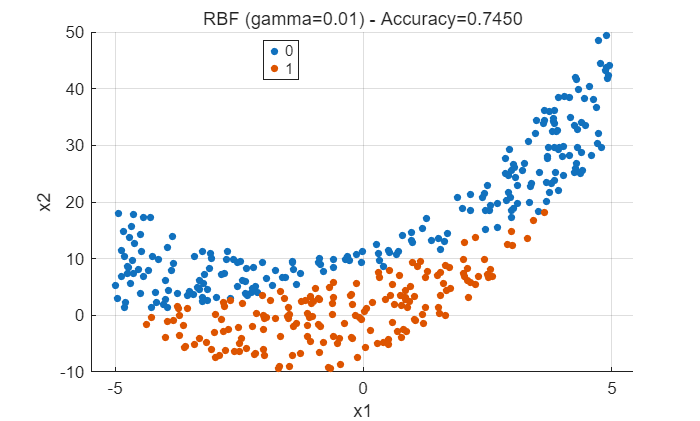


X_train = trainTbl{:, ["x1","x2"]};
y_train = trainTbl.label;

X_test  = testTbl{:, ["x1","x2"]};
y_test  = testTbl.label;

% 2) 基础模型：RBF SVM (gamma=0.01)
gamma0 = 0.01;
sigma0 = sqrt(1/(2*gamma0));   % MATLAB KernelScale

mdl0 = fitcsvm(X_train, y_train, ...
    "KernelFunction", "rbf", ...
    "KernelScale", sigma0, ...
    "BoxConstraint", 1, ...      % 默认相当于 C=1
    "Standardize", true);

pred0 = predict(mdl0, X_test);
acc0 = mean(pred0 == y_test);

testTbl.pred = pred0;
plotScatter(testTbl, "pred", sprintf("RBF (gamma=%.4g) - Accuracy=%.4f", gamma0, acc0));


disp("Base model:");

Base model:


disp(mdl0);

  ClassificationSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0    1]
           ScoreTransform: 'none'
          NumObservations: 400
                    Alpha: [321×1 double]
                     Bias: 2.4060
         KernelParameters: [1×1 struct]
                       Mu: [0.0234 11.2570]
                    Sigma: [3.0135 12.8287]
           BoxConstraints: [400×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [400×1 logical]
                   Solver: 'SMO'


  Properties, Methods



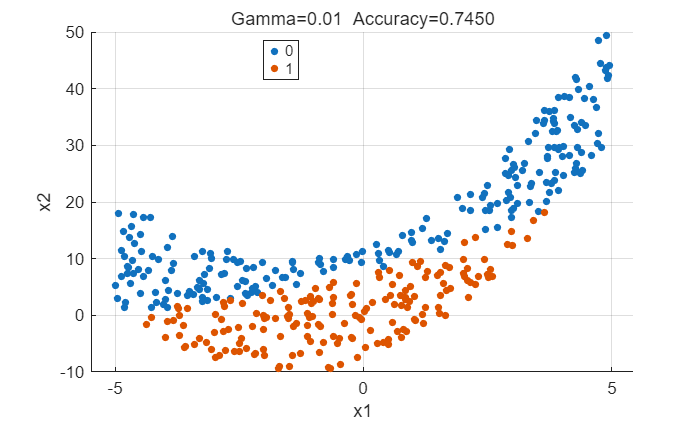

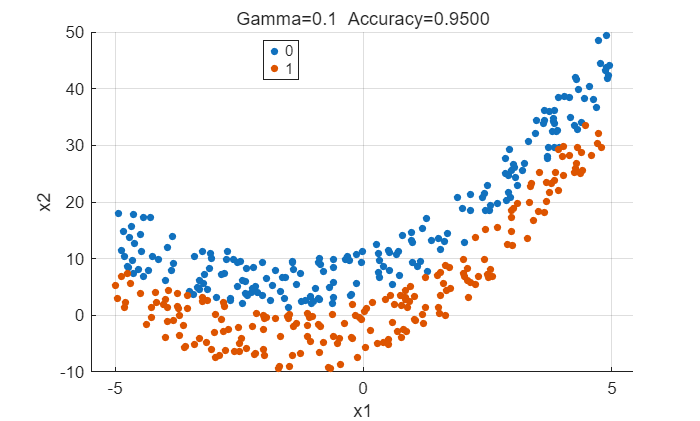

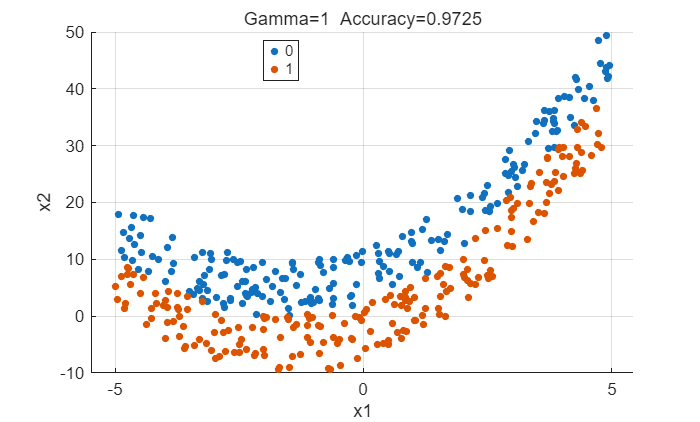

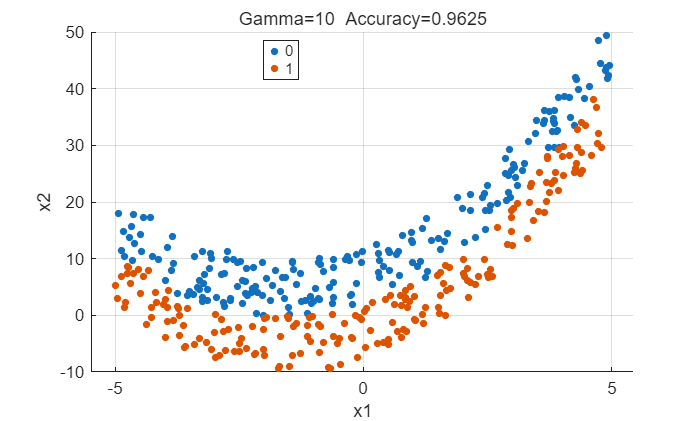

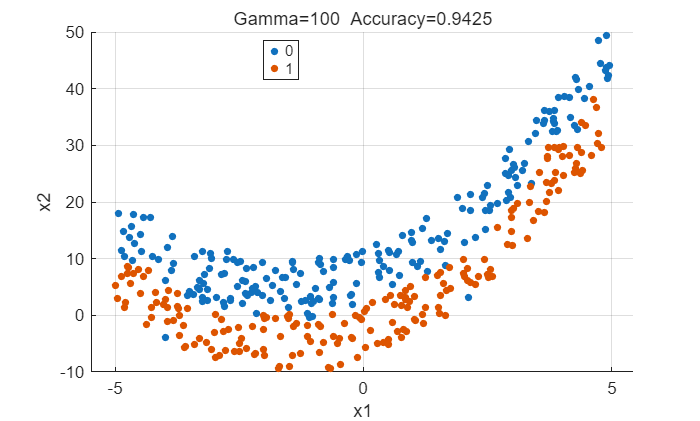

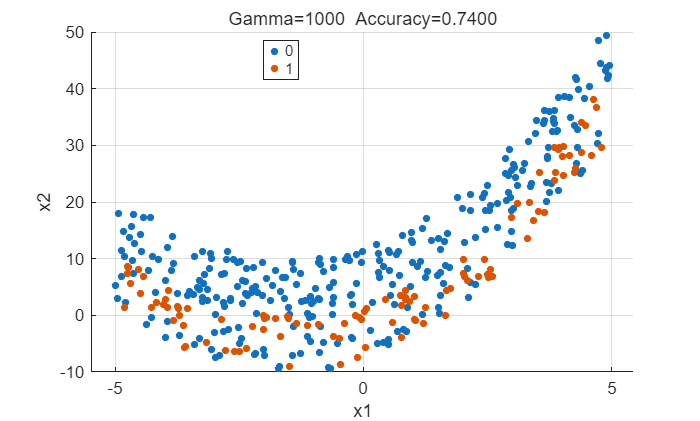


% 3) 循环不同 gamma（对应 Python/R 的 for g in ...）
gammas = [0.01, 0.1, 1, 10, 100, 1000];
for g = gammas
    sigma = sqrt(1/(2*g));

    mdl = fitcsvm(X_train, y_train, ...
        "KernelFunction", "rbf", ...
        "KernelScale", sigma, ...
        "BoxConstraint", 1, ...
        "Standardize", true);

    pred = predict(mdl, X_test);
    acc  = mean(pred == y_test);

    tmp = testTbl;
    tmp.pred = pred;
    plotScatter(tmp, "pred", sprintf("Gamma=%.4g  Accuracy=%.4f", g, acc));
end


% 4) 网格搜索：gamma in 0:0.1:10, C in 2^(1:5)（对应 tune）
gammaGrid = 0:0.1:10;
CGrid = 2.^(1:5);

bestAccCV = -inf;
bestGamma = NaN;
bestC = NaN;
bestMdl = [];

K = 5;  % 5-fold CV

for g = gammaGrid
    % gamma=0 时 RBF 没意义（sigma->inf），这里跳过或特殊处理
    if g == 0
        continue;
    end

    sigma = sqrt(1/(2*g));

    for C = CGrid
        mdl = fitcsvm(X_train, y_train, ...
            "KernelFunction", "rbf", ...
            "KernelScale", sigma, ...
            "BoxConstraint", C, ...
            "Standardize", true);

        cvMdl = crossval(mdl, "KFold", K);
        % kfoldLoss 默认是分类错误率，1-loss = 准确率
        accCV = 1 - kfoldLoss(cvMdl);

        if accCV > bestAccCV
            bestAccCV = accCV;
            bestGamma = g;
            bestC = C;
            bestMdl = mdl;
        end
    end
end

fprintf("\nBest CV Accuracy: %.4f\n", bestAccCV);


Best CV Accuracy: 0.9950


fprintf("Best gamma: %.4g\n", bestGamma);

Best gamma: 1.7


fprintf("Best C(BoxConstraint): %.4g\n", bestC);

Best C(BoxConstraint): 32



bestPred = predict(bestMdl, X_test);
bestAccTest = mean(bestPred == y_test);
fprintf("Test Accuracy with best model: %.4f\n", bestAccTest);

Test Accuracy with best model: 0.9625


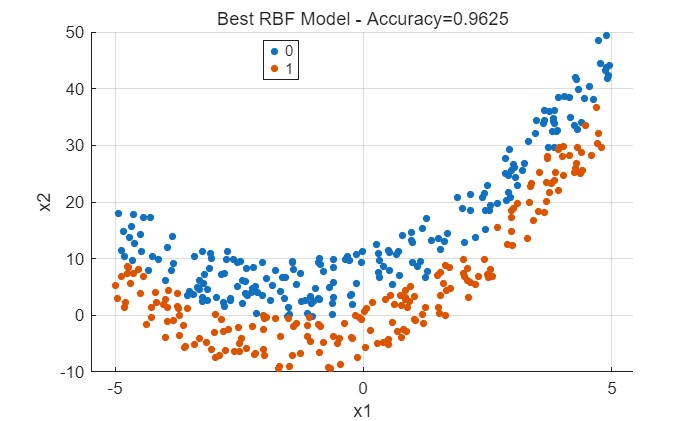


testTbl.pred = bestPred;
plotScatter(testTbl, "pred", sprintf("Best RBF Model - Accuracy=%.4f", bestAccTest));



%% ---------- local functions ----------
function tbl = makeDataset(nPerClass, seed)
    rng(seed);

    x1 = -5 + 10*rand(nPerClass,1);
    y1 = 2 + 3*x1 + x1.^2 + 10*rand(nPerClass,1);

    x2 = -5 + 10*rand(nPerClass,1);
    y2 = 2 + 3*x2 + x2.^2 - 10*rand(nPerClass,1);

    X = [x1 y1; x2 y2];
    label = [zeros(nPerClass,1); ones(nPerClass,1)];

    tbl = array2table(X, "VariableNames", ["x1","x2"]);
    tbl.label = categorical(label);
end

function plotScatter(tbl, colorCol, ttl)
    figure("Color","w");
    gscatter(tbl.x1, tbl.x2, tbl.(colorCol));
    xlabel("x1"); ylabel("x2");
    title(ttl);
    grid on;
end
toc

历时 23.171035 秒。
